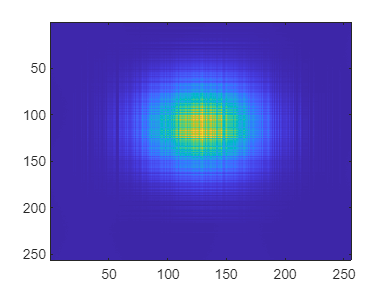

clear;

load("waves.mat");
ftwaves = fft2(waves);

imagesc(waves);

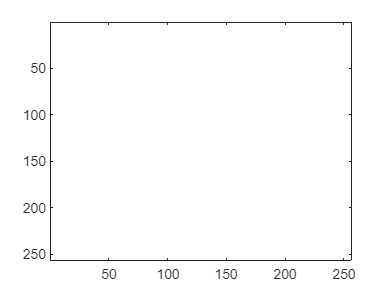

imagesc(abs(ftwaves)); %black :)

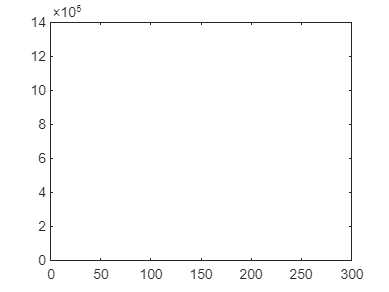

plot(abs(ftwaves))

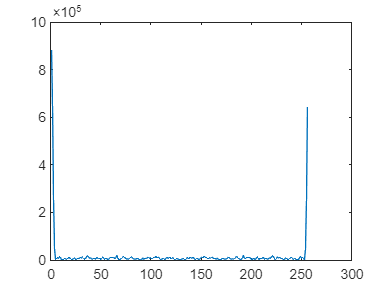

%plot(abs(ftwaves(1,:))- abs(ftwaves))
plot(abs(ftwaves(2,:)))



ftshitwaves = fftshift(ftwaves);
imagesc(abs(ftshitwaves))

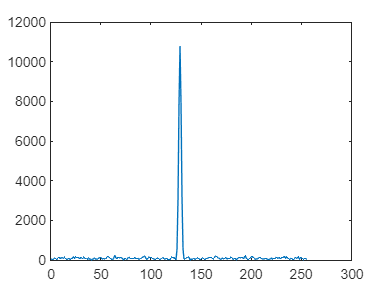

plot(abs(ftshitwaves(2,:)))

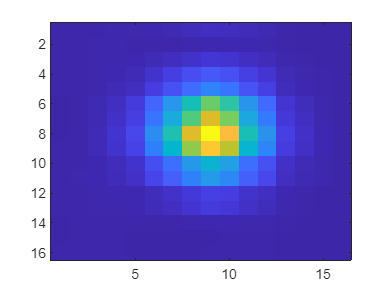


shortwaves = waves(1:16:256,1:16:256);
imagesc(abs(shortwaves));

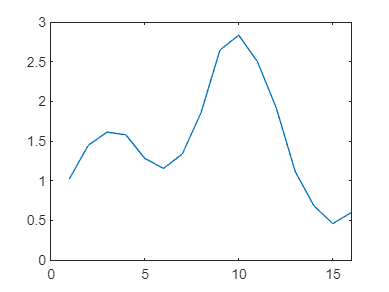

plot(abs(shortwaves(2,:)))


sus = ifft2(fftshift(fftshift(fft2(shortwaves))));
gus = ifft2(fft2(shortwaves)); % ^^ the same thing :) fftshift two times reveses the function
pus = fftshift(fftshift(shortwaves));
kus = shortwaves;
%sus = gus = pus = kus

imagesc(gus)

imagesc(sus)

%sus - gus = 0




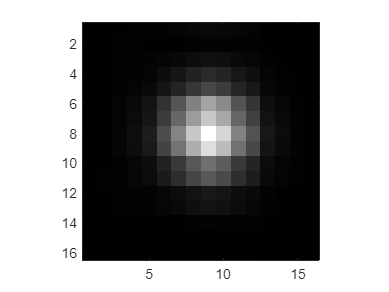



ORIGIM = imread('cameraman.tif');
ORIGIM = double(ORIGIM);
distance_map = zeros(16, 16);
for n  = 1:16
 for m = 1:16
    distance_map(n,m) = manhattan(n, m, 9, 9);
 end
end
axis image;
colormap gray;

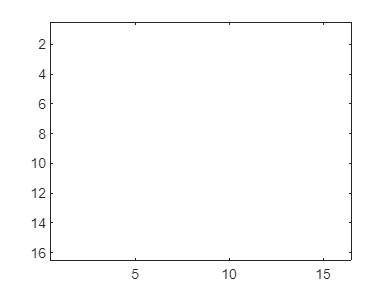

imagesc(distance_map);

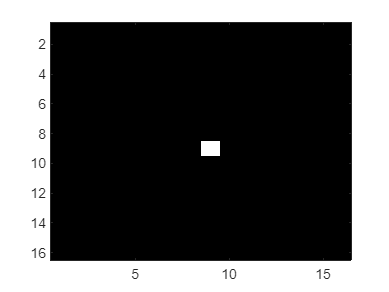

k = 0;
mask = (distance_map <= k);

% part 2
ftshortwaves0 = fftshift(fft2(shortwaves)) .* mask;
% rec0 = shortwaves * mask, shows the part of shortwaves which the mask lets through
rec0 = ifft2(fftshift(ftshortwaves0));

imagesc(ftshortwaves0); % shows the dot which the mask lets through

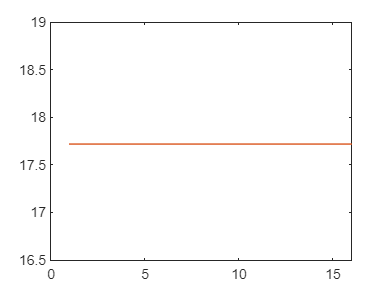

%imagesc(rec0)
plot(rec0)

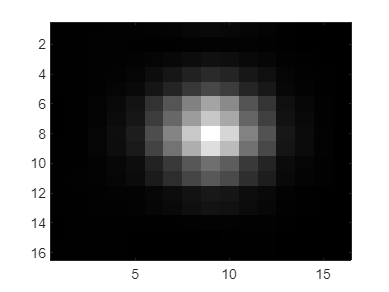

%imagesc(abs(rec0))

imagesc(shortwaves)

realG = abs(real(rec0))

realG =    17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.

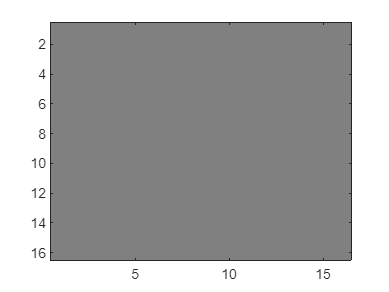

%realG = real(rec0);
imagesc(realG)


imagesc(abs(rec0))



SFFTIMAGE = complex(zeros(size(ORIGIM)));
for k  = 1:16:size(ORIGIM,1)-15
 for m = 1:16:size(ORIGIM,2)-15
  SFFTIMAGE(k:k+15,m:m+15)=fftshift(fft2(ORIGIM(k:k+15,m:m+15)));
 end
end
RECIM = complex(zeros(size(ORIGIM)));
for mthres = 1:max(mask(:))+1
 for k  = 1:16:size(ORIGIM,1)-15
  for m = 1:16:size(ORIGIM,2)-15
%   select the correct subimage from SFFTIMAGE   
    RECIM(k:k+15,m:m+15) = ifft2(fftshift(SFFTIMAGE(k:k+15,m:m+15)));
%   mask, shift and inverse transform. Store result in  RECIMAGE
    RECIMAGE(k:k+15,m:m+15) = abs(RECIM(k:k+15,m:m+15));
  end
 end
 figure(1);imagesc(ORIGIM)
 figure(2);imagesc(RECIMAGE);
 drawnow
 pause
end